In this script, we will solve the case of a **Quarter Plane Wedge**, with a shear load S on the vertical side.

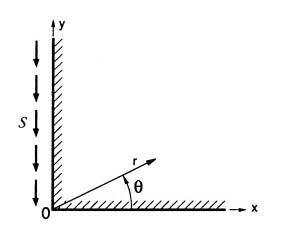

clc; clear all; close all;
evalc('WedgeProblem');
syms S;

We set the following boundary conditions-

- At $\theta =\frac{\pi }{2}$, $\sigma_{r\theta } \left(r,\frac{\pi }{2}\right)=-S$ and $\sigma_{\theta } \left(r,\frac{\pi }{2}\right)=0$

- At $\theta =0$, $\sigma_{r\theta } \left(r,0\right)=0$ and $\sigma_{\theta } \left(r,0\right)=0$

Thus the 4 equations satisfying the boundary conditions turn out to be-

eq1 = subs(sigma_rt,theta,pi/2) == -S

$$eq1 = 2\,A_{2}-A_{4}=-S$$

eq2 = subs(sigma_t,theta,pi/2) == 0

$$eq2 = 2\,A_{3}-2\,A_{1}+\pi \,A_{4}=0$$

eq3 = subs(sigma_rt,theta,0) == 0

$$eq3 = -2\,A_{2}-A_{4}=0$$

eq4 = subs(sigma_t,theta,0) == 0

$$eq4 = 2\,A_{1}+2\,A_{3}=0$$

[A1_sol,A2_sol,A3_sol,A4_sol] = solve(eq1,eq2,eq3,eq4,[A1,A2,A3,A4])

$$A1\_sol = \frac{\pi \,S}{8}$$

$$A2\_sol = -\frac{S}{4}$$

$$A3\_sol = -\frac{\pi \,S}{8}$$

$$A4\_sol = \frac{S}{2}$$

Hence, the final stress function, $\phi_{\textrm{final}}$ for the problem is-

phi_final = subs(phi_ob,[A1,A2,A3,A4],[A1_sol,A2_sol,A3_sol,A4_sol]);
disp(phi_final)

$$-r^{2}\,\left(\frac{\pi \,S}{8}-\frac{S\,\theta }{2}+\frac{S\,\sin\left(2\,\theta \right)}{4}-\frac{\pi \,S\,\cos\left(2\,\theta \right)}{8}\right)$$

stress_polar = polarStressMatrix(phi_final);
sigma_r = stress_polar(1,1)

$$sigma\_r = S\,\theta -\frac{\pi \,S}{4}+\frac{S\,\sin\left(2\,\theta \right)}{2}-\frac{\pi \,S\,\cos\left(2\,\theta \right)}{4}$$

sigma_t = stress_polar(2,2)

$$sigma\_t = S\,\theta -\frac{\pi \,S}{4}-\frac{S\,\sin\left(2\,\theta \right)}{2}+\frac{\pi \,S\,\cos\left(2\,\theta \right)}{4}$$

sigma_rt = stress_polar(1,2)

$$sigma\_rt = \frac{S\,\cos\left(2\,\theta \right)}{2}-\frac{S}{2}+\frac{\pi \,S\,\sin\left(2\,\theta \right)}{4}$$

sigma_tr = stress_polar(2,1)

$$sigma\_tr = \frac{S\,\cos\left(2\,\theta \right)}{2}-\frac{S}{2}+\frac{\pi \,S\,\sin\left(2\,\theta \right)}{4}$$

Timoshenko's Paradox is the apparent inconsistency of $\sigma_{\textrm{xy}}$ at x=y=0. $\sigma_{\textrm{xy}}$ becomes 0 as $y\to 0$ and becomes S as $x\to 0$. Also  $\sigma_{\textrm{xy}}$ becomes $\infty$ as both$x\;\textrm{and}\;y\to 0$. 

syms x y;
phi_final_cart = simplify(subs(phi_final,[r,theta],[sqrt(x^2+y^2),atan(y/x)]))

$$phi\_final\_cart = \frac{S\,\left(2\,x^{2}\,\mathrm{atan}\left(\frac{y}{x}\right)+2\,y^{2}\,\mathrm{atan}\left(\frac{y}{x}\right)-2\,x\,y-\pi \,y^{2}\right)}{4}$$

stress_cart = cartesianStressMatrix(phi_final_cart);
sigma_x = stress_cart(1,1)

$$sigma\_x = \frac{S\,\left(2\,x^{2}\,\mathrm{atan}\left(\frac{y}{x}\right)+2\,y^{2}\,\mathrm{atan}\left(\frac{y}{x}\right)+2\,x\,y-\pi \,x^{2}-\pi \,y^{2}\right)}{2\,\left(x^{2}+y^{2}\right)}$$

sigma_y = stress_cart(2,2)

$$sigma\_y = \frac{S\,\left(x^{2}\,\mathrm{atan}\left(\frac{y}{x}\right)+y^{2}\,\mathrm{atan}\left(\frac{y}{x}\right)-x\,y\right)}{x^{2}+y^{2}}$$

sigma_xy = stress_cart(1,2)

$$sigma\_xy = \frac{S\,y^{2}}{x^{2}+y^{2}}$$

sigma_yx = stress_cart(2,1)

$$sigma\_yx = \frac{S\,y^{2}}{x^{2}+y^{2}}$$